## **RaspberryPi with MATLAB Workshop**

**Required Software:**

- MATLAB 2023a (older versions may work too, but are not tested )

- MATLAB Support Package for RaspberryPi Hardware (Install the package under the Home tab --> Add-Ons)

**Required Hardware:**

- Raspberry Pi with a connected PCB and inserted SD card

- 3D printed Robot Arm

- Battery pack set to ON

- Ethernet cable (+ optional Ethernet to USB Adapter)

- Micro-USB cable

### Setup

1. Check that you have all required Hardware and Software

2. Connect the Batterie Pack and the Robot Arm to the correct Pins on the PCB

3. Connect the Raspberry Pi with an Ethernet Cable to your Laptop (use adapter if you don't have an ethernet connector).

4. Connect the Raspberry Pi's Powerport with the USB cable to your Laptop

5.  Wait 1-2 minutes for the raspberry pi to boot

6. In the IP list below, uncomment the IP corresponding to the label on the raspberry pi

7. Run the section below and wait for the connection to establish

% Try to connnect to raspi with IP
% If you have any problems with this step, please ask for help

% Set the IP of the raspi
% ip = '169.254.215.7'; % 11
ip = '169.254.162.237'; % 04
% ip = '169.254.146.104'; % 06
% ip = '169.254.212.152'; % 15
% ip = '169.254.82.77'; % 10
% ip = '169.254.212.196'; % 07
% ip = '169.254.232.81'; % 03
% ip = '169.254.199.208'; % 12

raspberry_pi = raspi(ip,'pi','raspberry'); 

8. Run the section below to configure the servos on Pin 22 and Pin 23

front_servo = servo(raspberry_pi,23);
back_servo = servo(raspberry_pi,22);
front_servo.MaxPulseDuration = 0.00250;
front_servo.MinPulseDuration = 0.0005;
back_servo.MaxPulseDuration = 0.00250;
back_servo.MinPulseDuration = 0.0005;   

9. Run the section below to command the angles of the front and back servo

% The maximum range for the back servor [0°, 180°]
% and for the front servo is [-90° , 90°] 

angle_back = 45; %deg
angle_front = 45; %deg

%Add offsets to the angles if necessary
%angle_back = min(max(angle_back + offset_back, 0),180);
%angle_front = min(max(angle_front + offset_front, -90), 90);

back_servo.writePosition(angle_back);
front_servo.writePosition(90-angle_front); % <- the 90 degrees is due to our choice of coordinates (see below)

And simultaniously plot the robot.

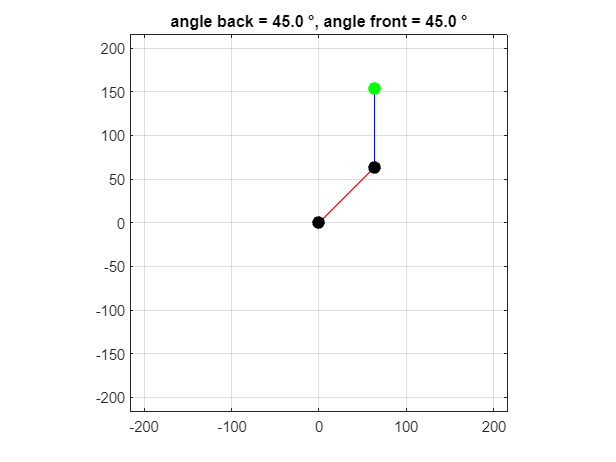

addpath("Live_Script_Helper_Files");
clf
plotRobot(angle_back, angle_front);

Make sure the physical position of the robot approximatly matches the plot. If not try to add an offset to the angle in  the section above.

### Forward Kinematics

In robotics, we usually care most about the position of the tip of the robot. This tip is called the endeffector. Forward Kinematics describes the common problem of localizing the endeffector in the coordinate frame using the given angles q1 and q2.

1. **TODO:** Write a function that calculates the position of endeffektor E of the robot. We choose the following Coordinate System.

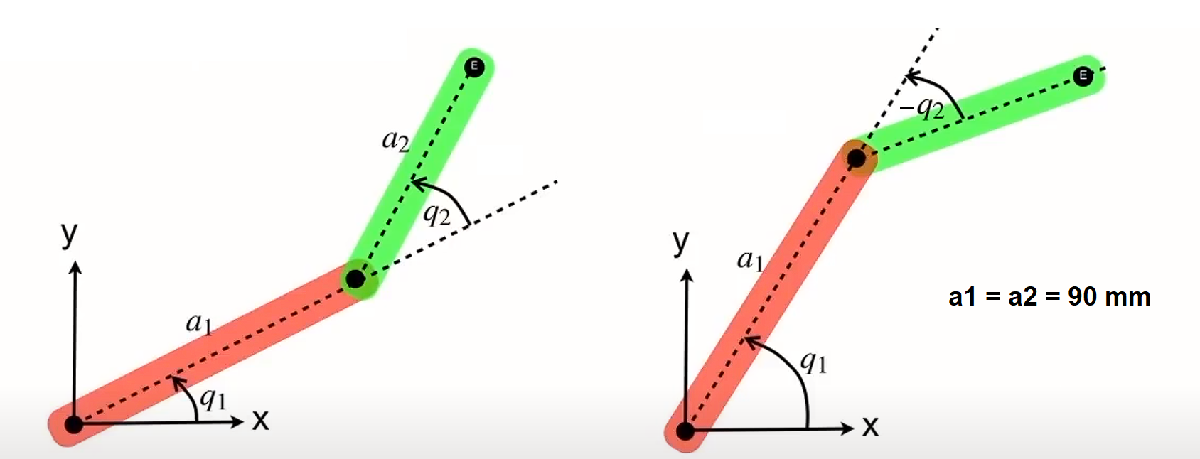

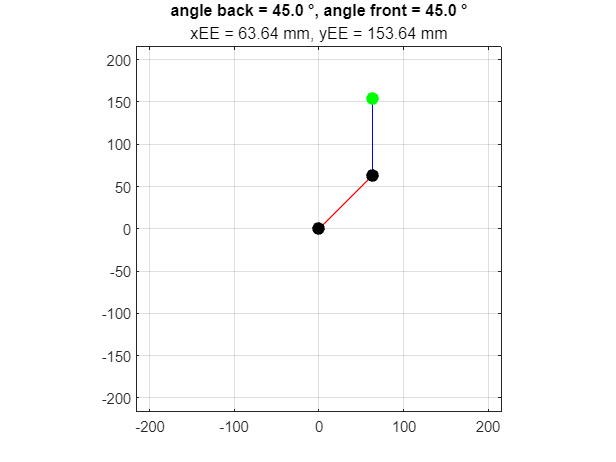

%Desired angles of the robot
angle_back = 45; %deg
angle_front = 45; %deg

% Modify the forwardKinematics.m file to calculate the endeffector position
% x_EE and y_EE
[x_EE, y_EE] = forwardKinematics(angle_back,angle_front);

%Add the position of the endeffektor in the plot
clf
plotRobot(angle_back, angle_front);
subtitle(sprintf("xEE = %.2f mm, yEE = %.2f mm", x_EE, y_EE));

**Workspace**

Since both servos are limited by their maximum angle, the robot arm is not able to reach all possible points in its circumference. The set of all points a robot can reach is called the workspace.

The goal in this task is to plot the workspace in the same plot as the robot to visualize all points the robot can reach.

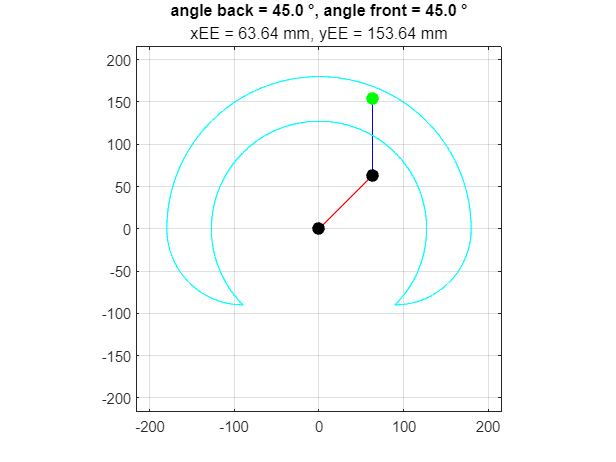

%Desired angles of the robot
angle_back = 45; %deg
angle_front = 45; %deg

%Plot the robot
plotRobot(angle_back, angle_front);

hold on

%Get the boundary points enclosing the workspace
[x_boundary, y_bonudary] = getWorkspace();

% Plot the workspace in the same plot
plot(x_boundary, y_bonudary, 'c-');

hold off

Great now we have all possible points the robot can reach in this configuration! We are ready to move to the classic challenge of robotics: Inverse Kinematics.

### Inverse Kinematics

Lets say our robot is in this configuration:

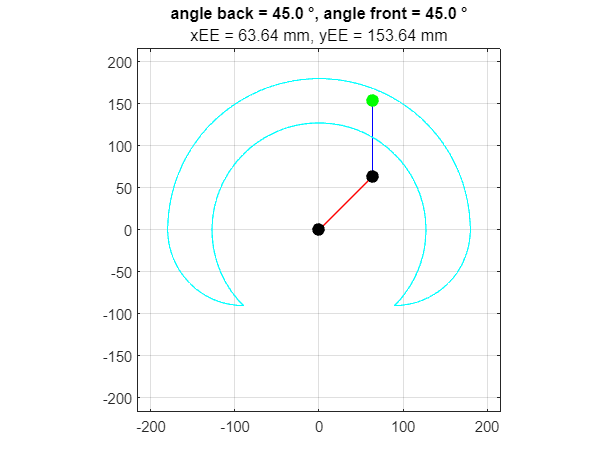

angle_back = 45;
angle_front = 45;

%Plot the robot with the calculated angles
plotRobot(angle_back,angle_front);

%Then we can calculate our endeffector position using the forwardKinematics
[x_EE, y_EE] = forwardKinematics(angle_back,angle_front);

%Add the position of the endeffektor in the plot
plotRobot(angle_back, angle_front);
subtitle(sprintf("xEE = %.2f mm, yEE = %.2f mm", x_EE, y_EE));

Imagine now, that our task is to move the endeffektor position to a desired location (x_des, y_des). For example here:

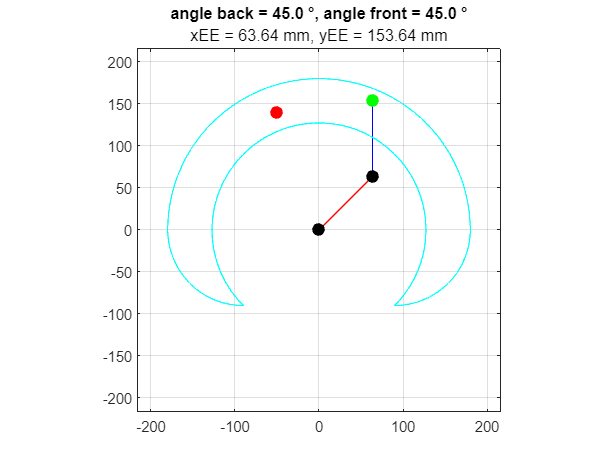

%Desired endeffektor position of the robot
x_des = -50; %mm
y_des = 140; %mm

%Lets visualize this
hold on
h_marker = plot(x_des, y_des, '-o', 'MarkerSize', 8, ...
        'MarkerEdgeColor', 'red', ...
        'MarkerFaceColor', 'red', ...
        'Tag', 'myMarker');
hold off

How can we now change to servo angles so that the endeffector will reach the desired position?

This is a classic problem in robotics called inverse kinematics.

The solution to this problem is found using the jacobi matrix which is defined as the derivative of the forwardKinematics with respect of the joint angles:

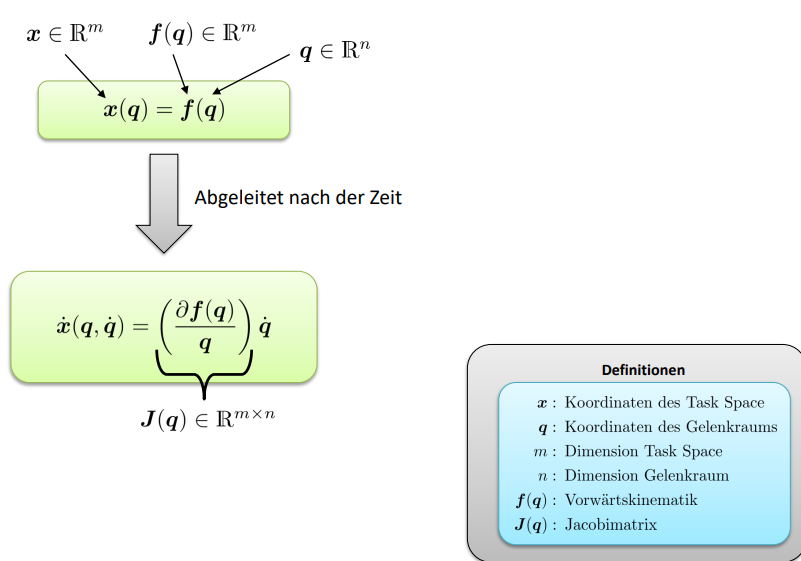

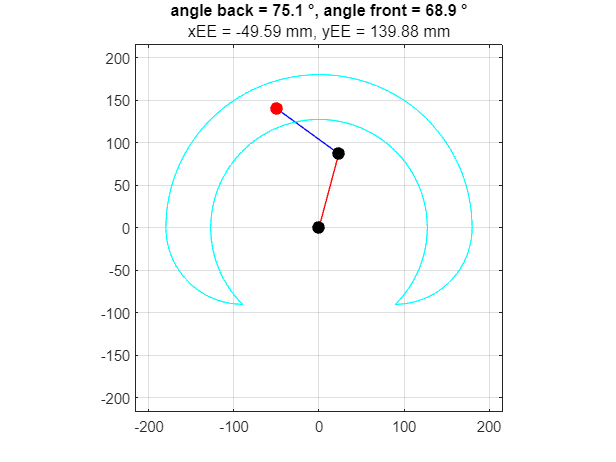

% The jacobi matrix (here 2x2) can be calculated for a given joint configuration:
J = getJacobi(angle_back,angle_front);

% Compute the pseudo-inverse of the Jacobian matrix
J_inv = pinv(J);

%Calculate dx and dy with a small step size (like a learning rate in gradient descent)
stepsize = 0.4;
dx = (x_des-x_EE)*stepsize;
dy = (y_des-y_EE)*stepsize;

% Calculate the desired change in joint angles (in radians)
delta_theta = J_inv * [dx; dy];
delta_theta = rad2deg(delta_theta);

angle_back = angle_back + delta_theta(1);
angle_front = angle_front + delta_theta(2);

%Update the robot
plotRobot(angle_back, angle_front);
[x_EE, y_EE] = forwardKinematics(angle_back, angle_front);
subtitle(sprintf("xEE = %.2f mm, yEE = %.2f mm", x_EE, y_EE));
hold on
h_marker = plot(x_des, y_des, '-o', 'MarkerSize', 8, ...
        'MarkerEdgeColor', 'red', ...
        'MarkerFaceColor', 'red', ...
        'Tag', 'myMarker');
hold off